load('1cupX.mat')
load('1cupY.mat')

userfit = fittype(['a*x+b'])

userfit =      일반 모델:
     userfit(a,b,x) = a*x+b

% ff = fit(X, Y, userfit, 'StartPoint', 1)
ff = fit(X, Y, userfit)

ff =      일반 모델:
     ff(x) = a*x+b
     계수(신뢰한계: 95%):
       a =       1.425  (1.355, 1.495)
       b =       1.067  (1.043, 1.092)

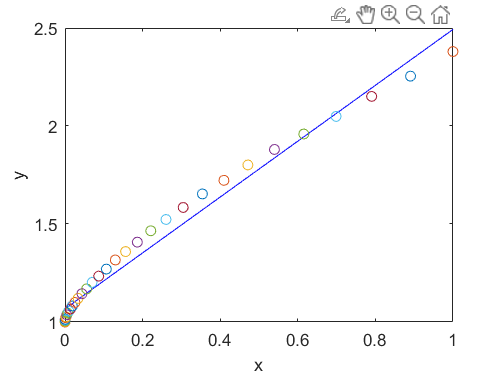

plot(ff, '-b')
legend('off')


for i=1:length(Y)
    hold on
    plot(X(i,1),Y(i,1),'o')
end

load('1cupX0.mat')
load('1cupY2.mat')


userfit = fittype(['a*x+1'])

userfit =      일반 모델:
     userfit(a,x) = a*x+1

ff = fit(X0, Y2, userfit, 'StartPoint', 1)

ff =      일반 모델:
     ff(x) = a*x+1
     계수(신뢰한계: 95%):
       a =       3.348  (3.307, 3.388)

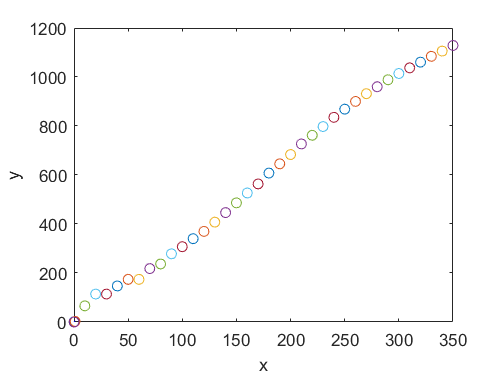

plot(ff, '-b')
legend('off')


for i=1:length(Y2)
    hold on
    plot(X0(i,1),Y2(i,1),'o')
end